%A generic pipelin to run flies
%Create ethologger obj. 
pathIN = '/Users/mehmetkeles/Downloads/20210817_Fly14_F_A_5d_8am-08172021175459DLC_resnet50_LiquidFoodDLCMar23shuffle1_200000-001.csv'

pathIN = '/Users/mehmetkeles/Downloads/20210817_Fly14_F_A_5d_8am-08172021175459DLC_resnet50_LiquidFoodDLCMar23shuffle1_200000-001.csv'

obj = ethologgerM(pathIN);

Creating the object using the csv file...
Reading CSV file (no filtering)


head(obj.Data)

ans = 8×106 table
    bodyparts_coords     a6_x      a6_y     a6_likelihood     a5_x      a5_y     a5_likelihood    atip_x    atip_y    atip_likelihood    headtip_x    headtip_y    headtip_likelihood    head_r_x    head_r_y    head_r_likelihood    head_l_x    head_l_y    head_l_likelihood    thor_ant_x    thor_ant_y    thor_ant_likelihood    thor_post_x    thor_post_y    thor_post_likelihood    t1_r_tip_x    t1_r_tip_y    t1_r_tip_likelihood    joint1_r_x    joint1_r_y    joint



%Turn 
[dfPose,dfLlh] = obj.getOrientedPose;
head(dfPose)

ans = 8×44 table
     a6_x      a6_y      a5_x      a5_y     atip_x    atip_y    headtip_x    headtip_y    prob_x    prob_y    thor_ant_x    thor_ant_y    thor_post_x    thor_post_y    head_x    head_y    halt_x    halt_y    t1_tip_x    t1_tip_y    t2_tip_x    t2_tip_y    t3_tip_x    t3_tip_y    joint1_x    joint1_y    joint2_x    joint2_y    joint3_x    joint3_y    joint1_top_x    joint1_top_y    joint2_top_x    joint2_top_y</

Right skewed histogram, llh threshold: 0.00016438 for headtip


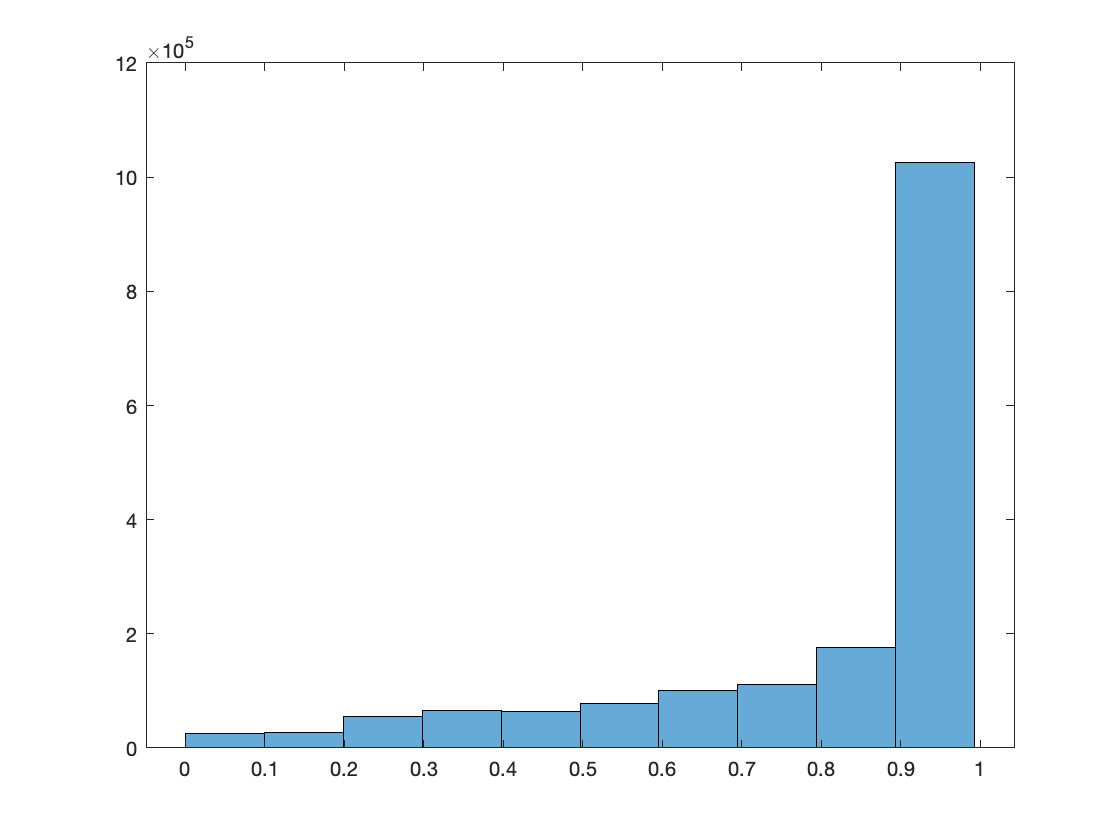

[dfTemp,pfilt] = ethologgerM.adaptive_llh_filter(dfPose,dfLlh,true);

dfPose = ethologgerM.median_filter(dfTemp,13); %13 seems to work best, can be modified depending on fps
spats = Spatiotemporal(obj.feature_cfg,30) %30 is the FPS here

[tDelta dNames] = spats.extract_delta_features(dfPose); %this takes sometime
[tSnap,sNames] = spats.extract_snap_features(dfPose);   
config = '/Users/mehmetkeles/Documents/GitHub/DLC-FlySleep/ethologgerM/config.mat'; %load CFG with structures
load(config)
frameExt = FrameExtraction(CFG.REST_INTERVALS_ARGS('min_rest'),CFG.REST_INTERVALS_ARGS('tol_duration'),CFG.REST_INTERVALS_ARGS('tol_percent'),CFG.REST_INTERVALS_ARGS('winsize'));

val_moving = frameExt.get_movement_values(tDelta,tDelta.Properties.VariableNames);
threshold = frameExt.get_threshold(val_moving,CFG.ACTIVITY_THRESHOLD_ARGS); 







